# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 4*

## Before You Start

In this script you will perform calculations with transfer-functions. In addition to the commands already used, the following MATLAB commands will be used:

- `tf `and `zpk,` to create transfer-function objects;

- `feedback,` to calculate the feedback connection of systems;

- `pole` and `zero`, to calculate properties of transfer-functions;

- `step`, to calculate and plot step responses;

- `bode`, to calculate the frequency response;

 You will also use the following auxiliary commands:

- `minreal`, to perform pole-zero cancellations;

- `semilogx`, to plot in logarithmic scale.

## 4.1 Tracking, Sensitivity and Integral Control

The command `tf` creates a transfer-function object that MATLAB can work with. The arguments of `tf` are the transfer-function's numerator and denominator polynomials. For example:

% Linearized car model
pOverBHat = 73.3;
bOverMHat = 0.05;
pOverMHat = pOverBHat * bOverMHat;

% open loop
g = tf(pOverMHat, [1 bOverMHat])


g =
 
   3.665
  --------
  s + 0.05
 
Continuous-time transfer function.



construct a transfer-function object `g` that represents the linearized car model:


$$G(s) = \frac{\frac{p}{m}}{s + \frac{b}{m}}$$


The arguments of `tf` are the numerator and denominator polynomial coefficients.

Likewise, the following `tf` represents the integral controller:

% integral controller
ki = tf(1, [1 0])


ki =
 
  1
  -
  s
 
Continuous-time transfer function.



One can calculate various properties of transfer-functions, such as the poles:

pole(g)

ans = -0.0500

and zeros:

zero(g)


ans =

  0×1 empty double column vector



tf objects can be operated as you would symbolically. For example:

g * ki


ans =
 
     3.665
  ------------
  s^2 + 0.05 s
 
Continuous-time transfer function.



calculates the product of those two transfer-functions and

g + ki


ans =
 
  4.665 s + 0.05
  --------------
   s^2 + 0.05 s
 
Continuous-time transfer function.



calculates their sum.

The unit feedback connection of the car model with the integral controller can be calculated using the command `feedback`:

K = 0.05

K = 0.0500

h = feedback(K*g*ki, 1)


h =
 
         0.1833
  ---------------------
  s^2 + 0.05 s + 0.1833
 
Continuous-time transfer function.



The second argument, in this case the number 1, represents the unit feedback. feedback returns another `tf` object.

The command `step`, when called without output arguments, calculates the step response and produces a plot as in:

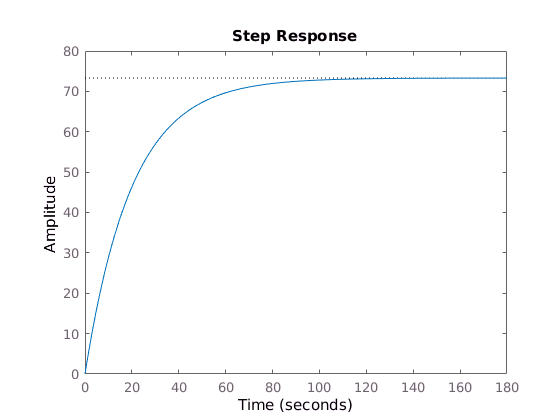

step(g)

Check out the similar commands `impulse` and `lsim`. Similarly, `bode` will produce a representation of the frequency response (more about this on Chapter 7):

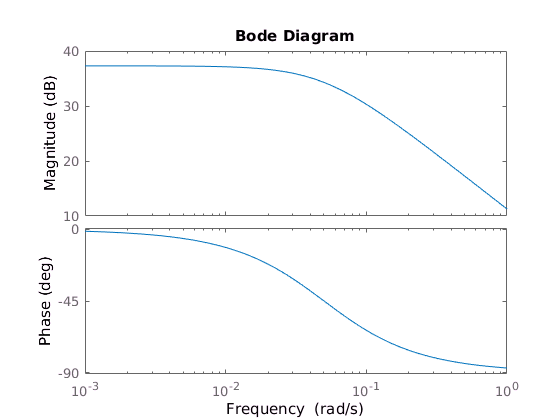

bode(g)

If output arugments are given to `step` and `bode` then the points necessary for reproducing these plots are returns. You will use this syntax below.

For a given gain 

K = 0.05

K = 0.0500

you can calculate the closed-loop reponse of the linear car model under integral control to a constant target velocity of $\bar{y} = 60$mph as follows:

h = feedback(K*g*ki, 1)


h =
 
         0.1833
  ---------------------
  s^2 + 0.05 s + 0.1833
 
Continuous-time transfer function.



yBar = 60

yBar = 60

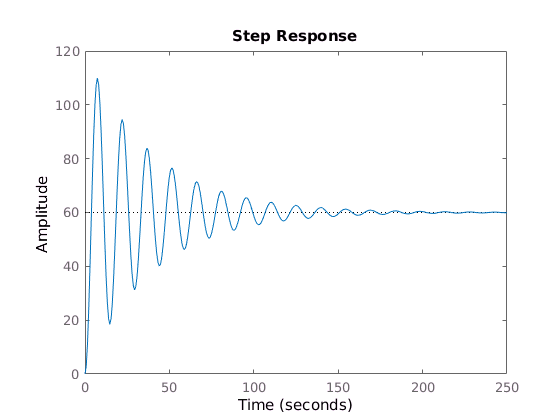

step(yBar * h)

Now calculate the closed-loop response of the linear car model under integral control to a constant target velocity of $\bar{y} = 60$mph to various values of $K$:

% step response

T = 60;
N = 4;
ks = [0.001 0.002 0.005 0.05];

taus = zeros(N,1);
yTildes = zeros(N,1);
Hs = zeros(N,1);

t = linspace(0,T,100);
y = zeros(N,length(t));

% closed loop
for i = 1 : N;
  K = ks(i);
  % linear model
  h = feedback(K*g*ki, 1);
  y(i,:) = step(yBar * h, t);
end

Now plot the responses:

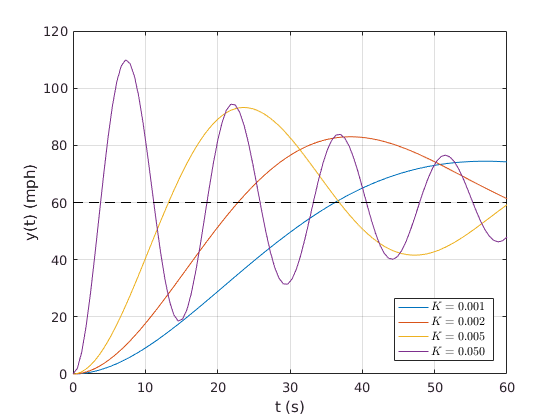

% Fig. 4.4: Step response with integral control
leg = [char(ones(N, 1) * double('$K = ')) num2str(ks','%4.3f') char(ones(N, 1) * double('$~'))];
plot(t, y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
h = legend(leg, 'Location', 'SouthEast');
set(h, 'Interpreter', 'latex')
grid on

## 4.2 Stability and Transient Response

Construct the proportional-integral controller:

% PI controller
kpi = tf([1 bOverMHat], [1 0])


kpi =
 
  s + 0.05
  --------
     s
 
Continuous-time transfer function.



with the zero chosen to perform a pole zero cancellation. Indeed, calculating the closed-loop transfer-function and converting to MATLAB's `zpk` object reveals the pole-zero cancellation:

h = feedback(kpi*g, 1)


h =
 
     3.665 s + 0.1833
  ----------------------
  s^2 + 3.715 s + 0.1833
 
Continuous-time transfer function.



zpk(h)


ans =
 
    3.665 (s+0.05)
  ------------------
  (s+3.665) (s+0.05)
 
Continuous-time zero/pole/gain model.



MATLAB's `minreal` performs the cancellation:

minreal(h)


ans =
 
    3.665
  ---------
  s + 3.665
 
Continuous-time transfer function.



Calculate the closed-loop response figures of the linear car model under proportional-integral control to a constant target velocity of $\bar{y} = 60$mph:

% Tab. 4.1:
N = 4;
yBars = [90 60 30 6];
ks = [0.03 0.05 0.1 0.5];
taus = 1./(pOverMHat * ks);
trs = 2.2 * taus;
kis = bOverMHat * ks;

colNames = {'yBar', 'Kp', 'Ki', 'tau', 'tr'};
tab4_1 = table(yBars', ks', kis', taus', trs','VariableNames', colNames);
tab4_1 = tab4_1(end:-1:1,:)

tab4_1 =     yBar     Kp       Ki       tau        tr  
    ____    ____    ______    ______    ______

     6       0.5     0.025    0.5457    1.2005
    30       0.1     0.005    2.7285    6.0027
    60      0.05    0.0025     5.457    12.005
    90      0.03    0.0015     9.095    20.009


Calculate the complete response and associated control inputs: 

T = 15;

% step response

t = linspace(0,T,100);
y = zeros(N,length(t));
u = zeros(N, length(t));

for i = 1 : N;
  Kp = ks(i);
  Ki = Kp * bOverMHat;

  % linear model
  h = feedback(Kp*g*kpi, 1);
  y(i,:) = step(yBar * h, t);
end

and plot the reponses:

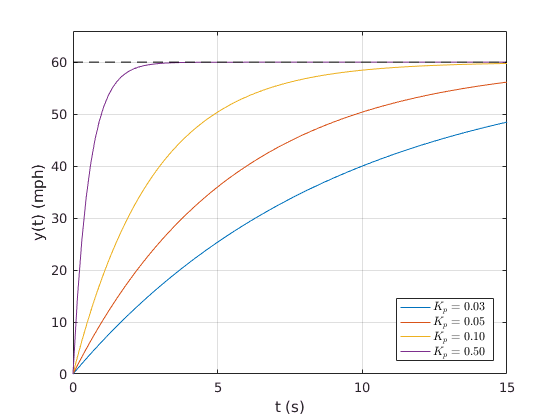

% Fig. 4.6: Step response with proportional-integral control
leg = [char(ones(N, 1) * double('$K_p =')) num2str(ks','%3.2f') char(ones(N, 1) * double('$~'))];
plot(t, y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
ylim([0 1.1*yBar])
h = legend(leg, 'Location', 'SouthEast');
set(h, 'interpreter', 'latex')
grid on

Calculate the closed-loop transfer-functions:


$$S = \frac{1}{1 + G K}, \quad
H = \frac{G K}{1 + G K}, \quad
D = \frac{G}{1 + G K}$$


for proportional, integral and proportional-integral control:

% Proportional
Kp = 0.05

Kp = 0.0500


Sp = feedback(1, Kp*g);
Hp = feedback(Kp*g, 1);
Dp = feedback(g, Kp);

% Integral
Ki = 0.002

Ki = 0.0020


Si = feedback(1, Ki*g*ki);
Hi = feedback(Ki*g*ki, 1);
Di = feedback(g, Ki*ki);

% Proportional-integral
Kp = 0.05

Kp = 0.0500

Ki = Kp * bOverMHat

Ki = 0.0025


Spi = feedback(1, Kp*g*kpi);
Hpi = feedback(Kp*g*kpi, 1);
Dpi = feedback(g, Kp*kpi);

 and plot the corresponding frequency responses using MATLAB's `bode`:

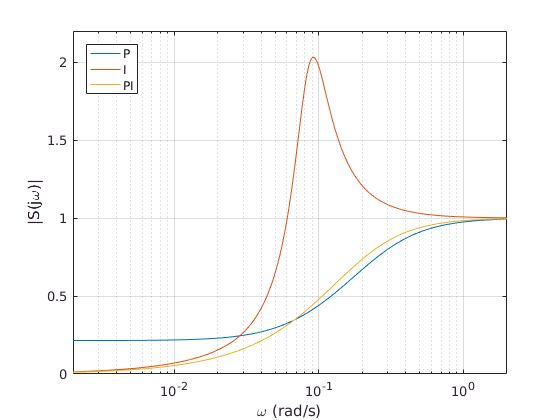

% Fig. 4.7: Sensitivity with P, O and PI controllers
w0 = 2e-3;
w1 = 2e0;
w = logspace(log10(w0), log10(w1), 200);

N = 3;
mag = zeros(N, length(w));
phs = zeros(N, length(w));

i = 1;
[mag(i,:), phs(i,:)] = bode(Sp, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Si, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Spi, w);

leg = {'P', 'I','PI'};
semilogx(w, mag);
xlabel('\omega (rad/s)')
ylabel('|S(j\omega)|')
legend(leg, 'Location', 'NorthWest')
xlim([w0 w1])
ylim([0 2.2])
grid

As with `step`, `bode` produces a plot when called without output arguments:

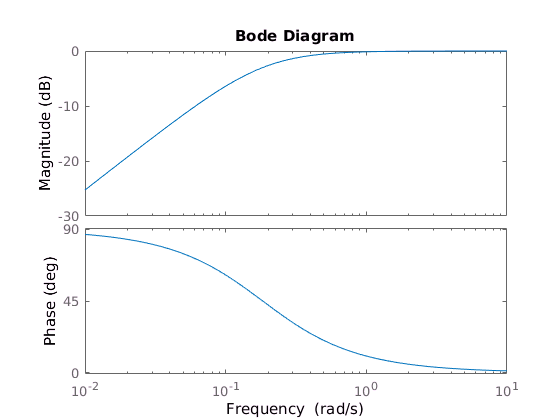

bode(Spi)

Note that the previous plot is a log-linear plot while `bode` is a log-log plot. Chapter 7 has much more on frequency response methods and Bode plots.

## 4.3 Integrator Wind-up

In order to assess the effects of integrator wind-up reconstruct the parameters of nonlinear model from Section 2.6:

% Nonlinear car model
pOverBHat = 73.3;
bOverMHat = 0.05;
pOverMHat = pOverBHat * bOverMHat;

alpha = 82.8;
beta = 1.2;

cOverMHat = alpha * bOverMHat;
dOverMHat = beta * cOverMHat;
dOverCHat = dOverMHat / cOverMHat;

and calculate the closed-loop step responses under proportional-integral control using `ode45:`

% Closed-loop step responses (nonlinear model)

% .
% v = -(c/m)atan(v/alpha) + (d/m) sat(u)
% .
% ei = e            % integrator
% e = (ybar - v)
% u = Kp e + Ki ei

% .
% x = [-(c/m)atan(x(1)/alpha) + (d/m) sat(Kp (ybar - x(1)) + Ki x(2))]
%     [ ybar - x(1) ]

xnl = {};
ynl = {};
einl = {};
unl = {};

ks = [0.03 0.05 0.1 0.5];
N = length(ks);
uMax = 3;

T = 15;
t = linspace(0, T, 200);

for i = 1 : N

    % nl closed-loop step-response
    Kp = ks(i);
    Ki = bOverMHat*Kp;
    f = @(t,x) [dOverMHat*min([uMax,Kp*(yBar-x(1))+Ki*x(2)])- ...
                cOverMHat*tan(x(1)/alpha); yBar-x(1)];
    sol = ode45(f, [0 T], [0; 0]);
    xnl{i} = deval(sol, t);
    ynl{i} = xnl{i}(1,:);
    xcnl{i} = Ki*xnl{i}(2,:); % integrator state
    enl{i} = yBar-ynl{i};
    unl{i} = Kp*(yBar-ynl{i})+Ki*xcnl{i};
    unl{i}(unl{i} > 3) = 3;
    i = i + 1;
    
end

Now plot the control inputs:

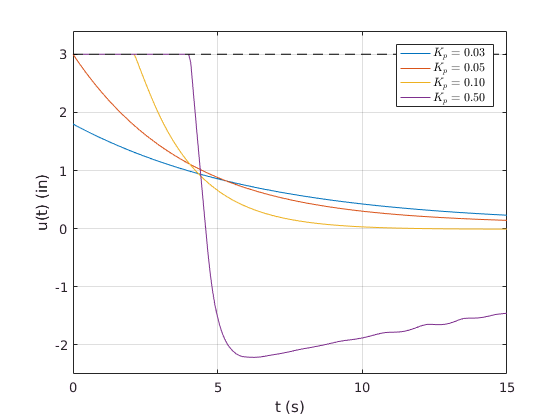

% Fig. 4.8:
leg = [char(ones(N, 1) * double('$K_p = ')) num2str(ks','%3.2f') char(ones(N, 1) * double('$~'))];
plot(t, unl{1}, ...
     t, unl{2}, ...
     t, unl{3}, ...
     t, unl{4}, ...
     [0 T], uMax*[1 1], 'k--');

xlabel('t (s)')
ylabel('u(t) (in)')
ylim([-2.5 3.4]);
h = legend(leg,'Location','NorthEast');
set(h, 'interpreter', 'latex')
grid on

and the responses:

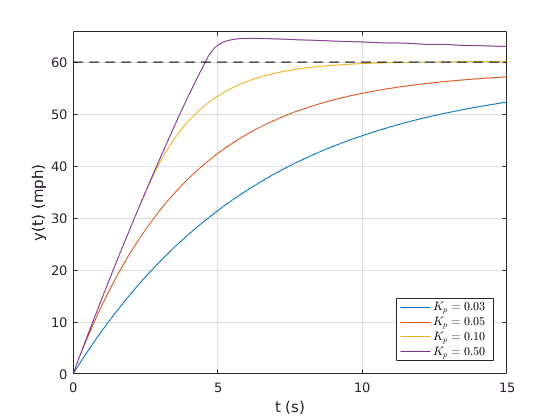

% Fig. 4.9
plot(t, ynl{1}, ...
     t, ynl{2}, ...
     t, ynl{3}, ...
     t, ynl{4}, ...
     [0 T], yBar*[1 1], 'k--');

xlabel('t (s)')
ylabel('y(t) (mph)')
h = legend(leg,'Location','SouthEast');
set(h, 'interpreter', 'latex')
ylim([0 1.1*yBar]);
grid on

Simulate for a little longer:

T = 80;
t = linspace(0, T, 200);

for i = 1 : N

    % nl closed-loop step-response
    Kp = ks(i);
    Ki = bOverMHat*Kp;
    f = @(t,x) [dOverMHat*min([uMax,Kp*(yBar-x(1))+Ki*x(2)])- ...
                cOverMHat*tan(x(1)/alpha); yBar-x(1)];
    sol = ode45(f, [0 T], [0; 0]);
    xnl{i} = deval(sol, t);
    ynl{i} = xnl{i}(1,:);
    xcnl{i} = Ki*xnl{i}(2,:); % integrator state
    enl{i} = yBar-ynl{i};
    unl{i} = Kp*(yBar-ynl{i})+Ki*xcnl{i};
    unl{i}(unl{i} > 3) = 3;
    i = i + 1;
    
end

and plot the integral component of the control:

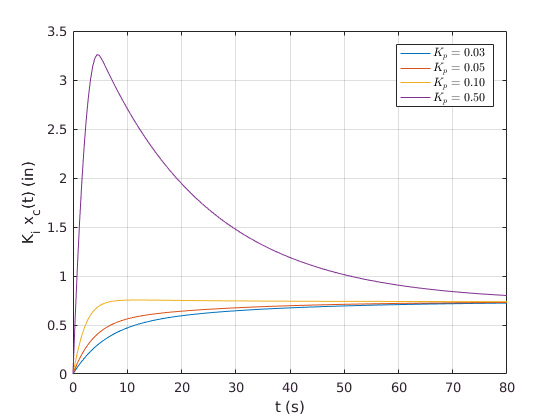

% Fig. 4.10
plot(t, xcnl{1}, ...
     t, xcnl{2}, ...
     t, xcnl{3}, ...
     t, xcnl{4});
xlabel('t (s)')
ylabel('K_i x_c(t) (in)')
h = legend(leg,'Location','NorthEast');
set(h, 'interpreter', 'latex')
grid on

## 4.5 Input Disturbance Rejection

Calculate the response of the linear car model under integral control to a change in slope (disturbance) from 0% to 10% slope:

G = 9.8 * 3600 / 1609;
thetaBar = atan(.1) % 10% slope

thetaBar = 0.0997

wBar = G/pOverMHat * sin(thetaBar)

wBar = 0.5953


ks = [0.001 0.002 0.005 0.05];

T0 = 10;
T = 200;

t = linspace(0,T - T0,200);
y = zeros(N,length(t));

for i = 1 : N;
  Kp = ks(i);

  % linear model
  d = feedback(g, Kp*ki);
  y(i,:) = step(-wBar * d, t);
end

y = [yBar*ones(N,2) yBar+y];

and plot the responses:

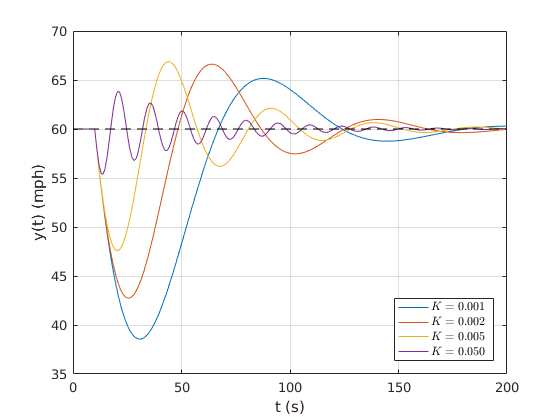

% Fig 4.12: Response to disturbance with integral control
leg = [char(ones(N, 1) * double('$K = ')) num2str(ks','%4.3f') char(ones(N, 1) * double('$~'))];
plot([0, T0, t+T0], y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
ylim([35 70])
h = legend(leg, 'Location', 'SouthEast');
set(h, 'Interpreter', 'latex')
grid on

Repeat with proportional-integral control:

ks = [0.03 0.05 0.1 0.5];
y = zeros(N,length(t));

for i = 1 : N;
  Kp = ks(i);
  
  Ki = Kp * bOverMHat;

  % linear model
  d = feedback(g, Kp*kpi);
  y(i,:) = step(-wBar * d, t);
end

y = [yBar*ones(N,2) yBar+y];

and plot the responses:

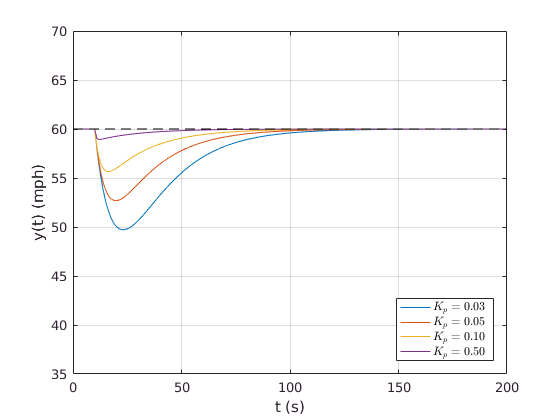

% Fig 4.13: Response to disturbance with proportional-integral control
leg = [char(ones(N, 1) * double('$K_p = ')) num2str(ks','%3.2f') char(ones(N, 1) * double('$~'))];
plot([0, T0, t+T0], y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
ylim([35 70])
h = legend(leg, 'Location', 'SouthEast');
set(h, 'interpreter', 'latex')
grid on

Plot the frequency response of the closed-loop transfer-function D(s) previously calculated:

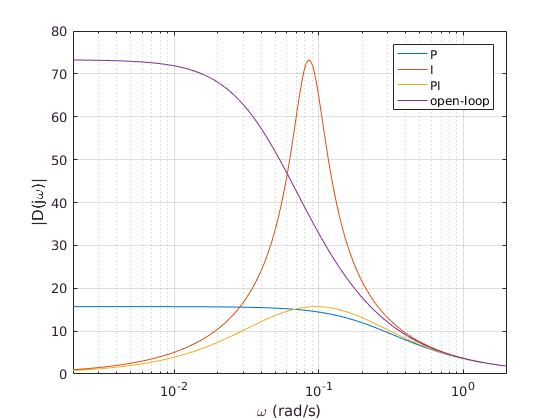

% Fig. 4.14: P, I and PI controllers

leg = {'P','I','PI','open-loop'};

N = 4;
mag = zeros(N, length(w));
phs = zeros(N, length(w));

i = 1;
[mag(i,:), phs(i,:)] = bode(Dp, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Di, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Dpi, w);

i = 4;
[mag(i,:), phs(i,:)] = bode(g, w);

semilogx(w, mag);

xlabel('\omega (rad/s)')
ylabel('|D(j\omega)|')
legend(leg, 'Location', 'NorthEast')
xlim([w0 w1])
grid

## 4.6 Measurement Noise

Plot the frequency response of the complementary sensitivity closed-loop transfer-function H(s) previously calculated:

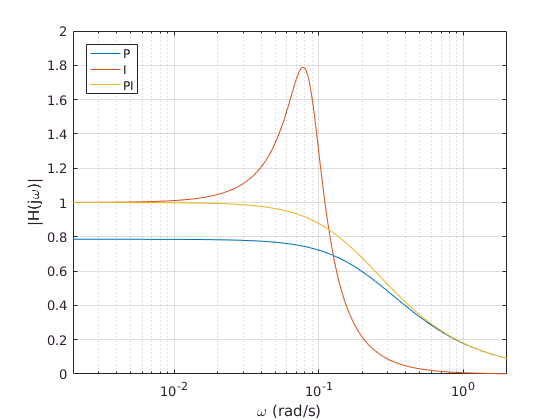

% Fig. 4.16: Complementary sensitivity for P, O and PI controllers

N = 3;
mag = zeros(N, length(w));
phs = zeros(N, length(w));

leg = {'P', 'I','PI'};

i = 1;
[mag(i,:), phs(i,:)] = bode(Hp, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Hi, w);

i = i + 1;
[mag(i,:), phs(i,:)] = bode(Hpi, w);

semilogx(w, mag);

xlabel('\omega (rad/s)')
ylabel('|H(j\omega)|')
legend(leg, 'Location', 'NorthWest')
xlim([w0 w1])
ylim([0 2])
grid

## 4.7 Pole-Zero Cancellations and Stability

Calculate the closed-loop response of the linear car model under proportional-integral control to a constant target velocity of $\bar{y} = 60$mph when the zero of the controller and the pole of the system do not perfectly match:

T = 20;

mmatch = [1 2 1.1 0.5];
M = length(mmatch);

t = linspace(0,T,100);
y = zeros(M,length(t));

leg = [char(ones(M, 1) * double('$\gamma = ')) num2str(round(100*mmatch)', '%3d') char(ones(M, 1) * double('\%$~'))];

i = 3;
for l = 1 : M;

  Kp = ks(i);
  Ki = mmatch(l) * Kp * bOverMHat;
  k = tf([1 Ki/Kp], [1 0]);

  % linear model
  h = feedback(Kp*g*k, 1);
  y(l,:) = step(yBar * h, t);

end

and plot the responses:

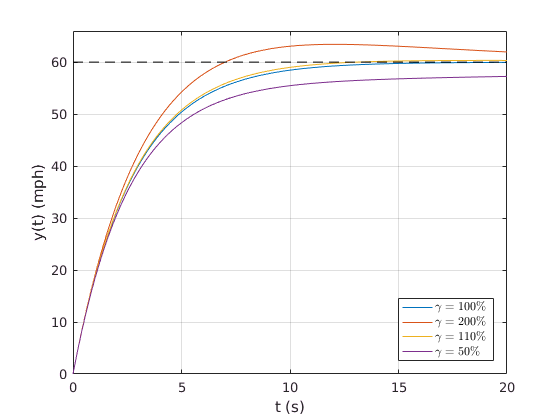

% Fig. 4.19: Step response with gain mismatch
plot(t, y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
ylim([0 1.1*yBar])
h = legend(leg, 'Location', 'SouthEast');
set(h, 'Interpreter', 'latex')
grid on